%Requirement 1

U=3600;
x=linspace(0,1,1000);
OCV=2.6+2.36*x-3.75*x.^2+2.5*x.^3;
disp("Open Circuit Voltage (OCV) when fully discharged " + OCV(1) + " Volts");

Open Circuit Voltage (OCV) when fully discharged 2.6 Volts


disp("Open Circuit Voltage (OCV) when fully charged " + OCV(end) + " Volts");

Open Circuit Voltage (OCV) when fully charged 3.71 Volts


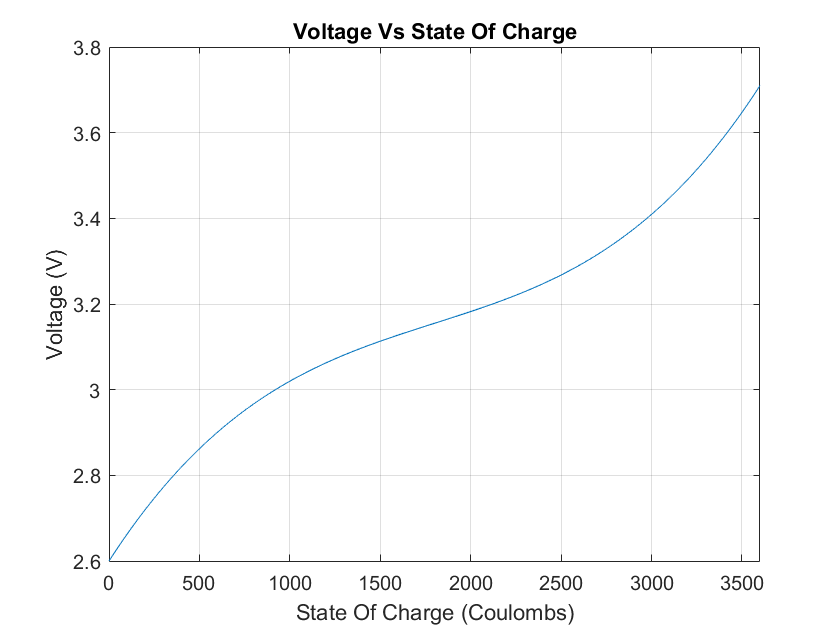


col=x.*U;
plot(col,OCV);
figure(1)
title("Voltage Vs State Of Charge")
xlabel("State Of Charge (Coulombs)")
ylabel("Voltage (V)")
xlim([0,3600])
grid on

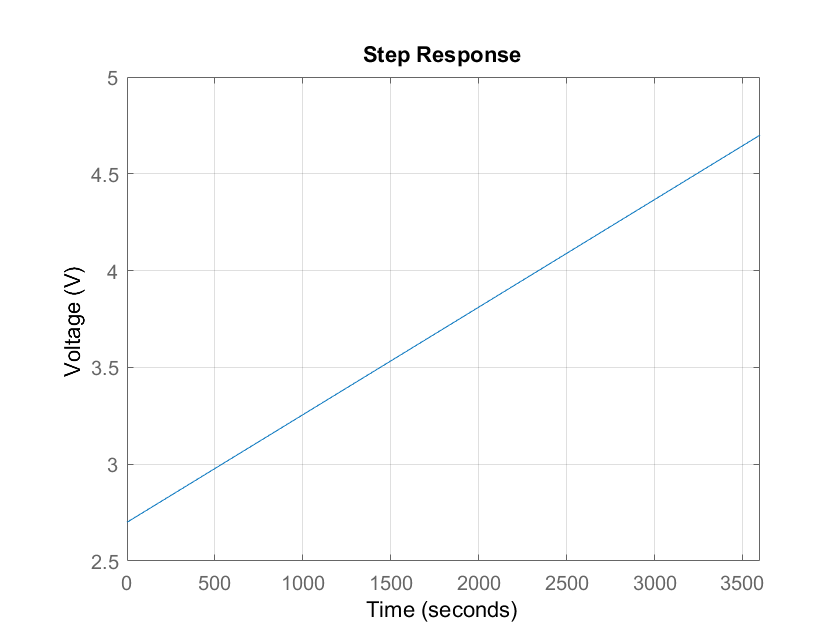


%Requirement 3+4

% Charge Capacity (Ah=3600 C)
Q=3600;
% Gamma (dOCV/dSOC)
G=2;
% Equivalent Series Resistnace (Ohms)
R=0.1;
% Equivalent Capacitance (Farads)
C=Q/G;
%Initial Voltage at 0 SOC (Volts)
V0= 2.6;

for
A = [0];
B = [1/Q];
C = [OCV];
D = [R + V0];
sys = ss(A,B,C,D);
figure(2)
step(sys, 3600) 
ylabel("Voltage (V)")
xlim([0,3600])
grid on

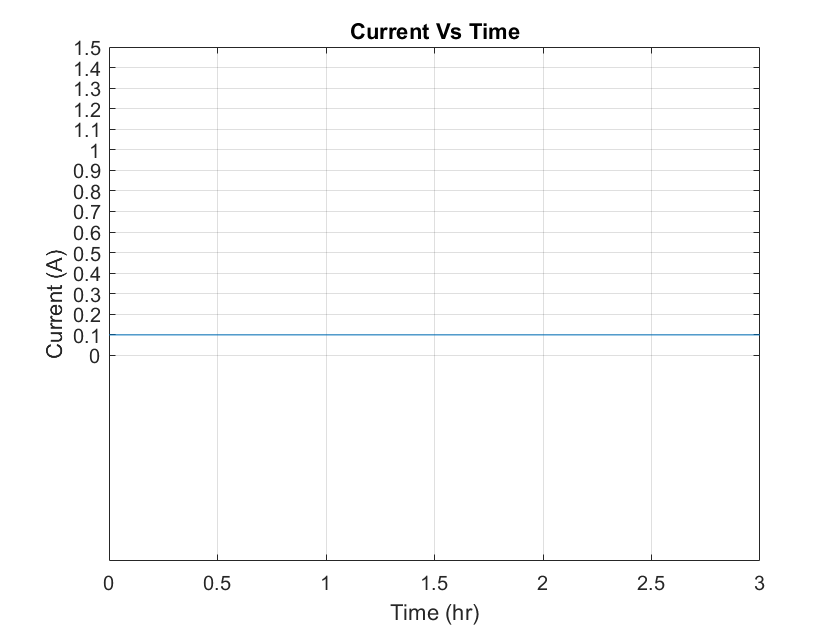

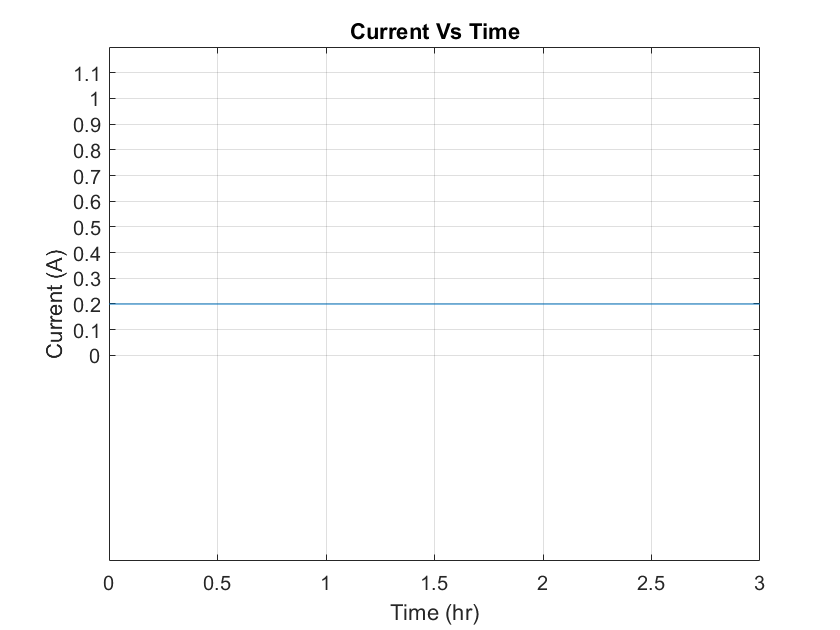

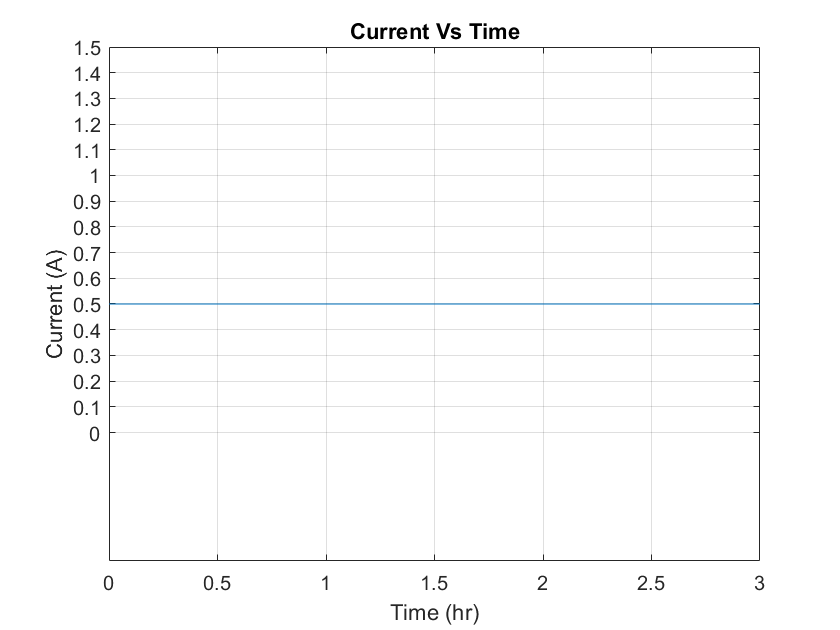

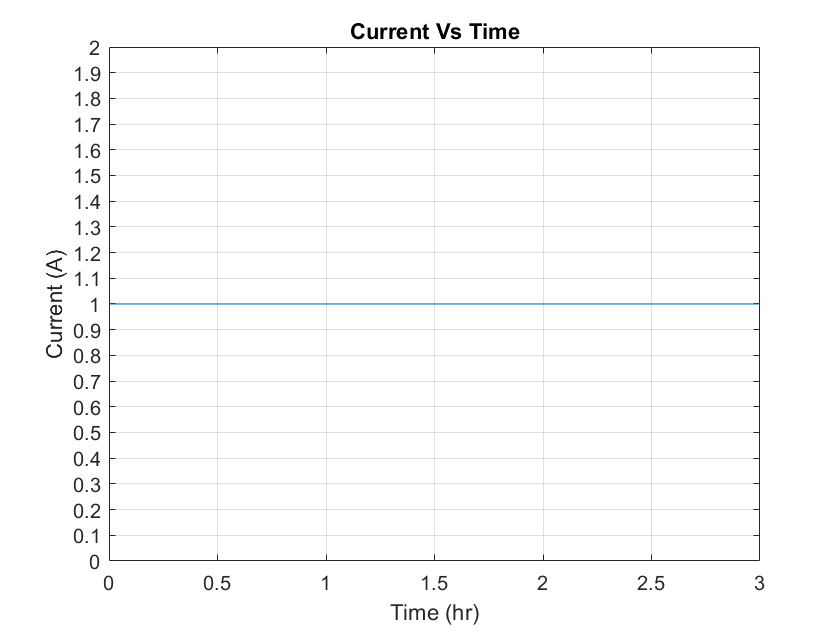

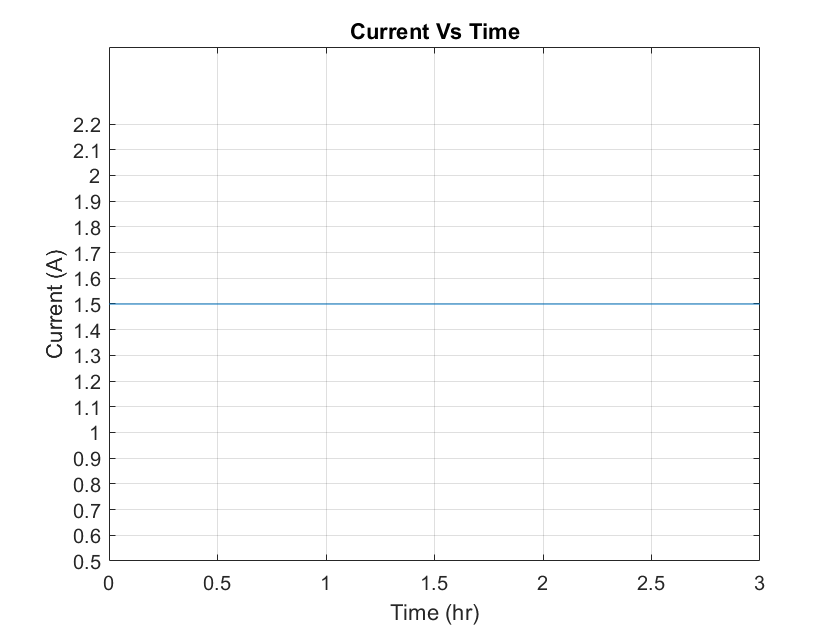

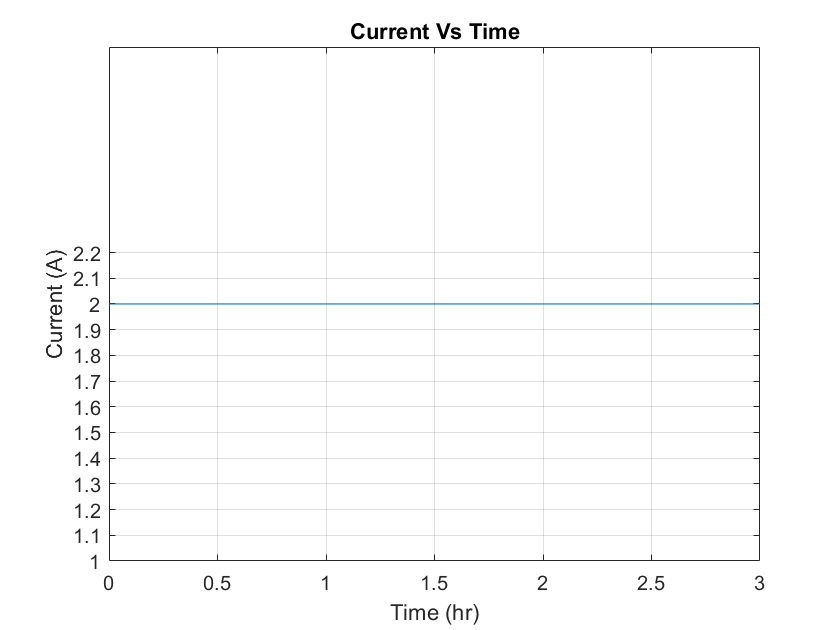


%Requirement 5+6

Q = 1;
C_rate = [0.1*Q 0.2*Q 0.5*Q 1*Q 1.5*Q 2*Q];
time = linspace(0,3,1000);
%I(t)=C-rate*Q
for i = 1:length(C_rate) 
    figure(2+i)
    plot(time, C_rate(i)*ones(1,length(time)))
    title("Current Vs Time")
    xlabel('Time (hr)')
    ylabel("Current (A)")
    xlim([0 3])
    yticks([0:0.1:2.2])
    grid on
end

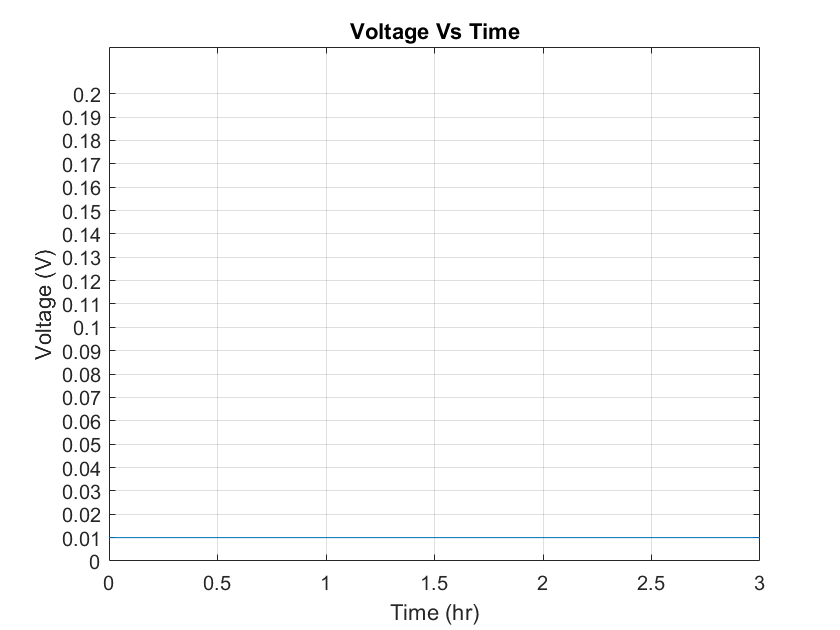

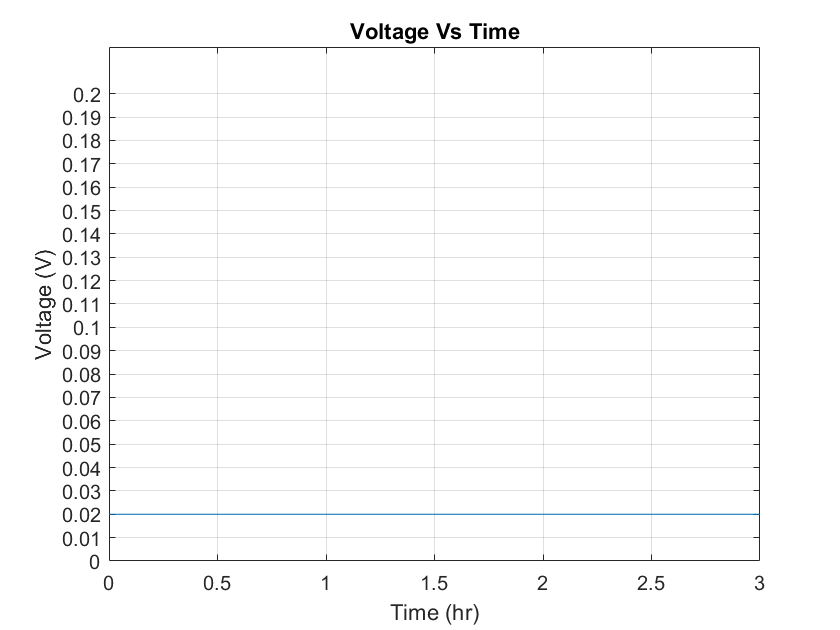

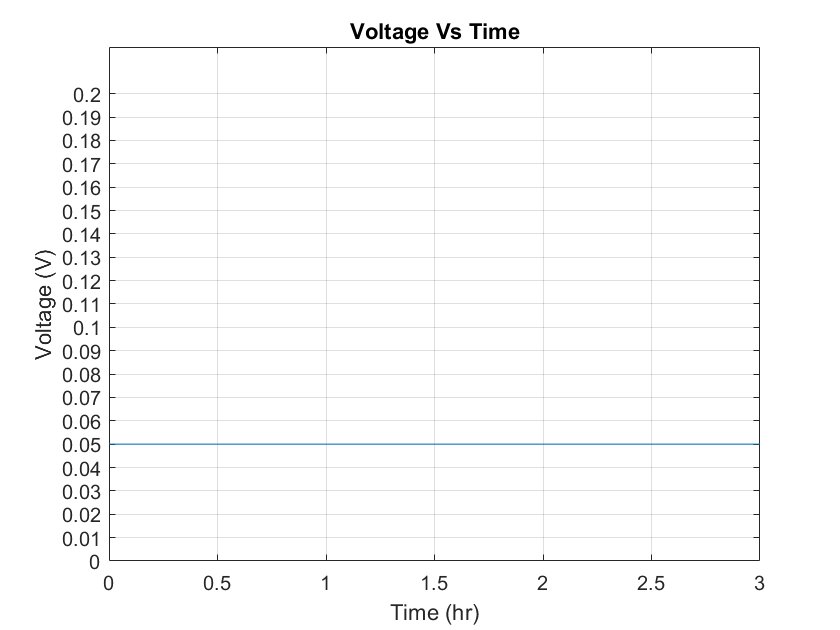

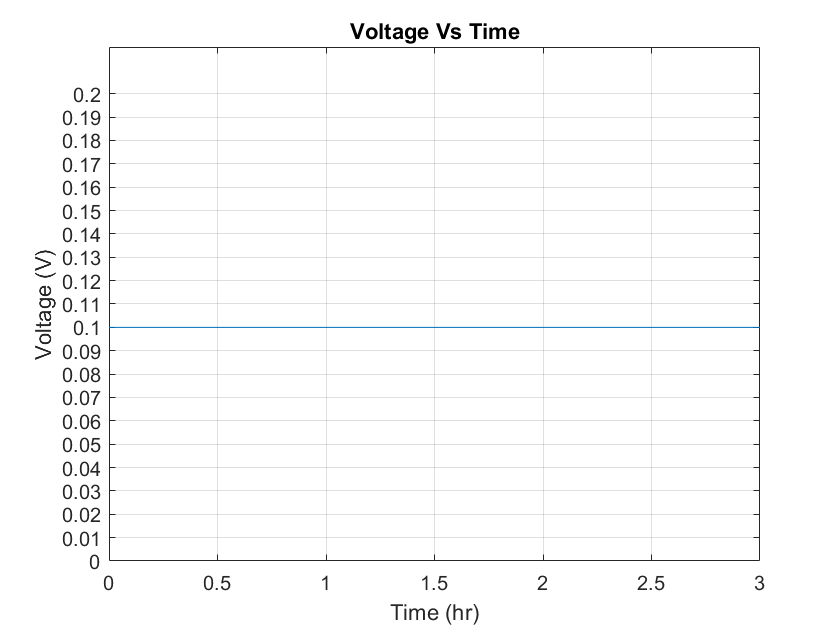

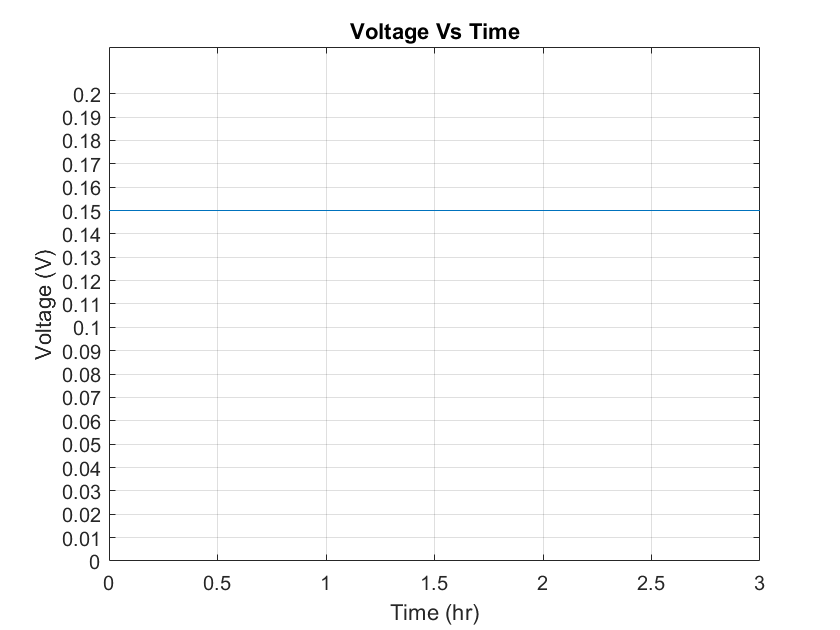

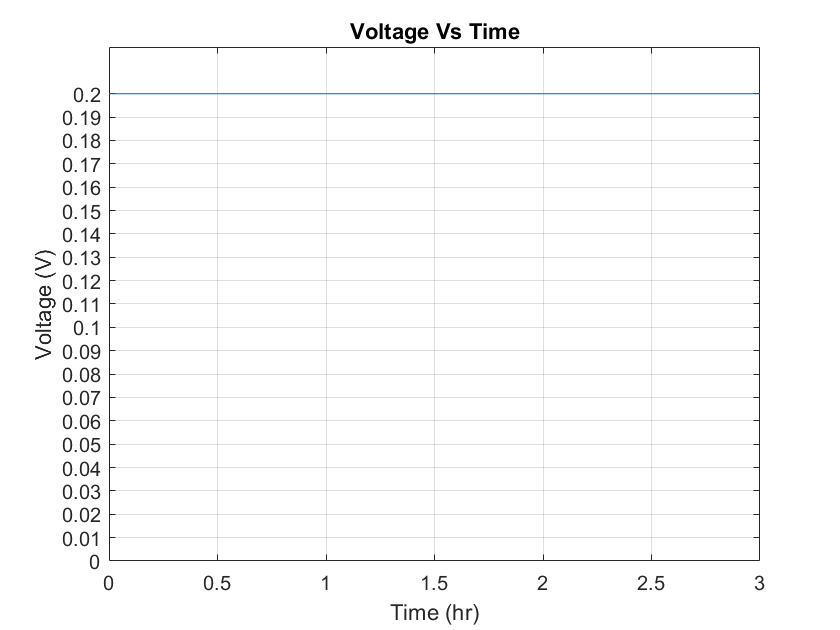


for i = 1:length(C_rate) 
    figure(8+i)
    plot(time, C_rate(i)*R*ones(1,length(time)))
    title("Voltage Vs Time")
    xlabel('Time (hr)')
    ylabel("Voltage (V)")
    xlim([0 3])
    ylim([0 0.22])
    yticks([0:0.01:0.2])
    grid on
end

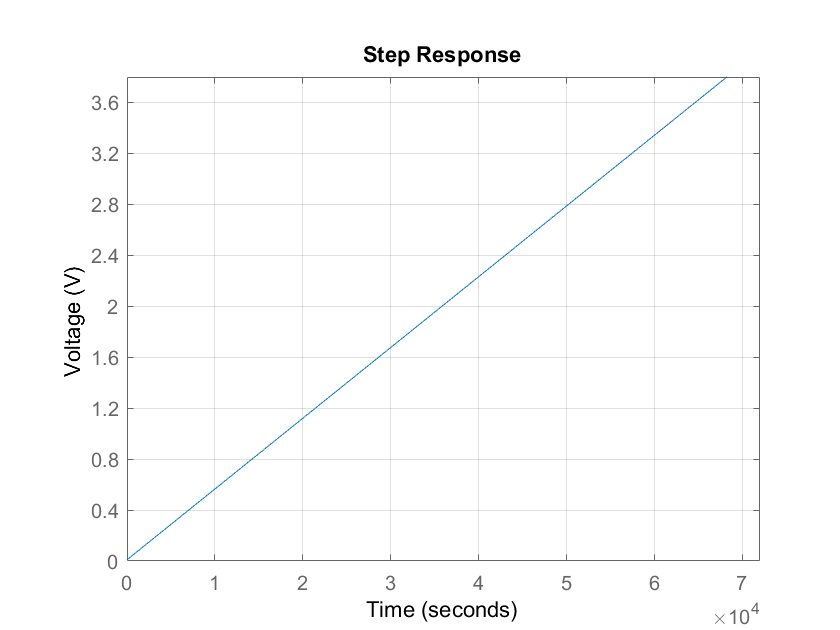

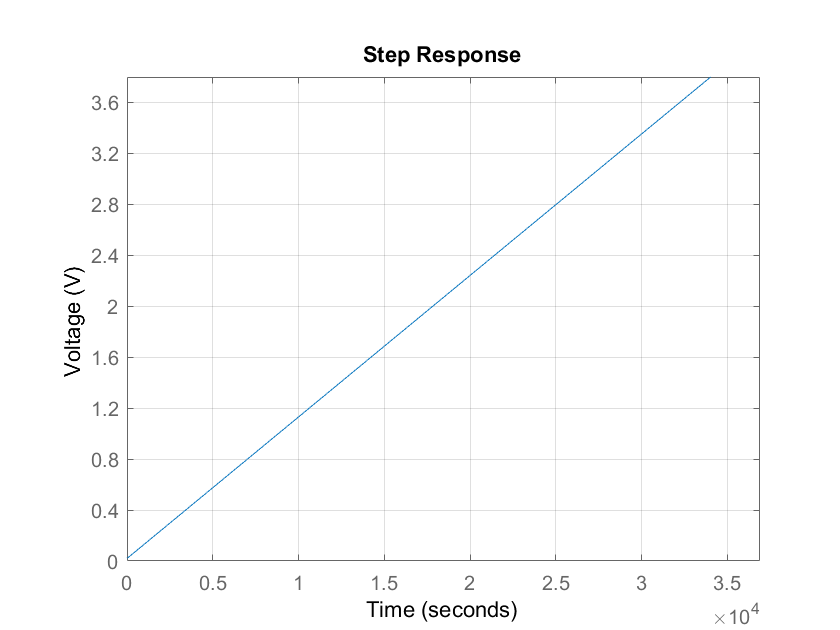

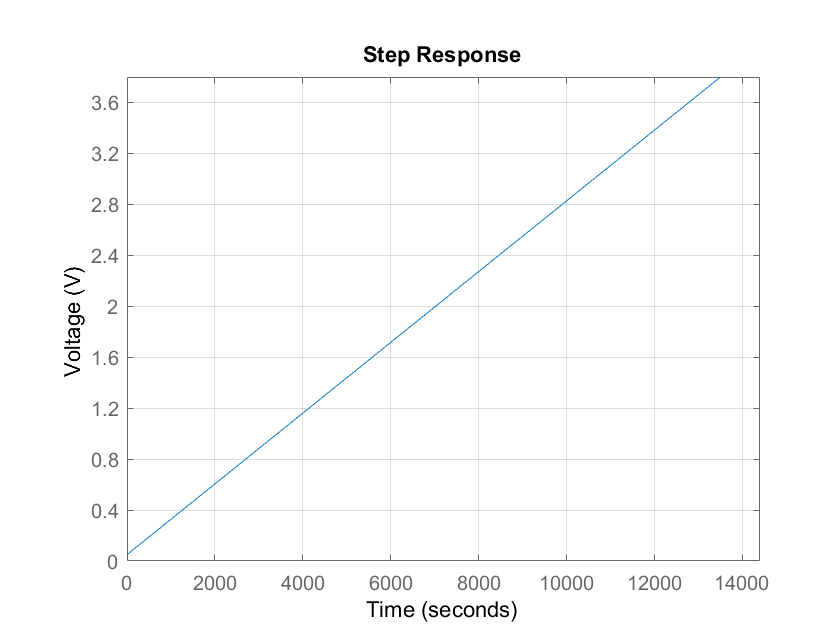

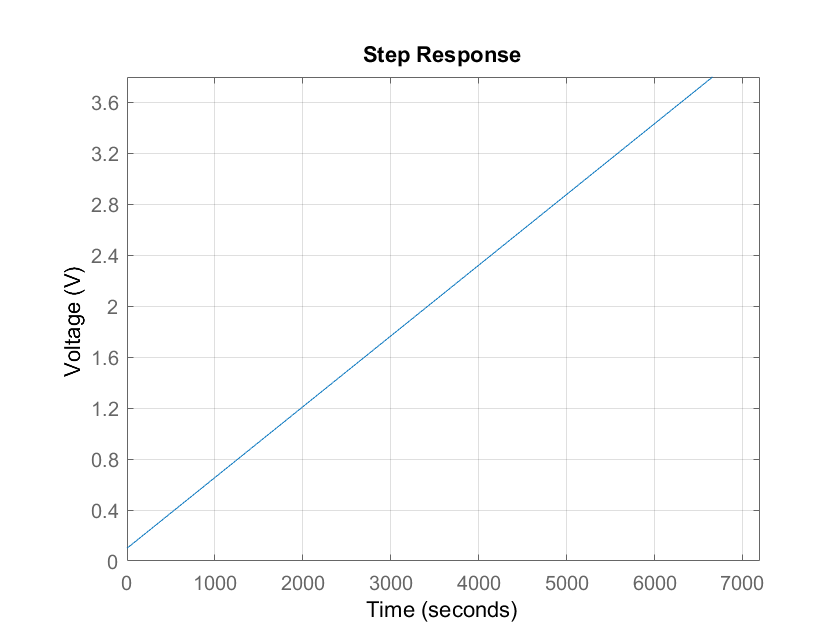

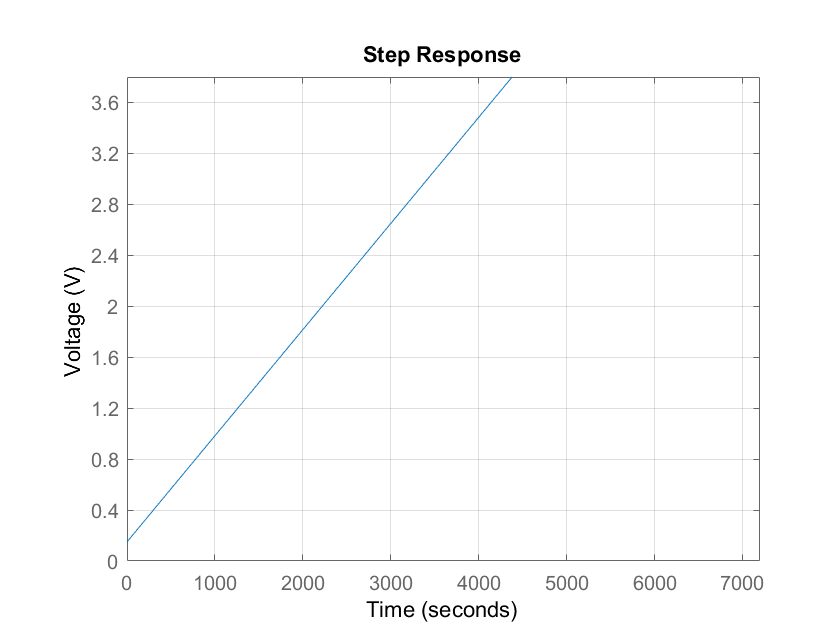

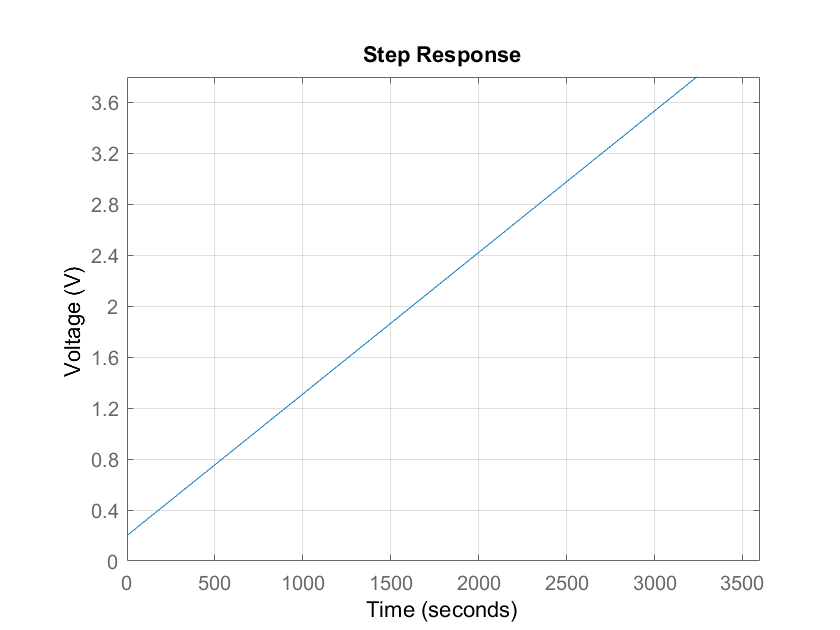


% Charge Capacity (Ah=3600 C)
Q=3600;
% Gamma (dOCV/dSOC)
G=2;
% Equivalent Series Resistnace (Ohms)
R=0.1;
% Equivalent Capacitance (Farads)
C=Q/G;
%Initial Voltage at 0 SOC (Volts)
V0=0;

A = [0];
B = [1/Q];
C = [G];
D = [R + V0];
sys = ss(A,B,C,D);
t_f = [72000 36900 14400 7200 7200 3600];
for i = 1:length(C_rate) 
    figure(14+i)
    opt = stepDataOptions('InputOffset',0 ,'StepAmplitude',C_rate(i));
    step(sys, t_f(i) ,opt) 
    ylabel("Voltage (V)")
    xlim([0 t_f(i)])
    ylim([0 3.8])
    yticks([0:0.4:4])
    grid on
end

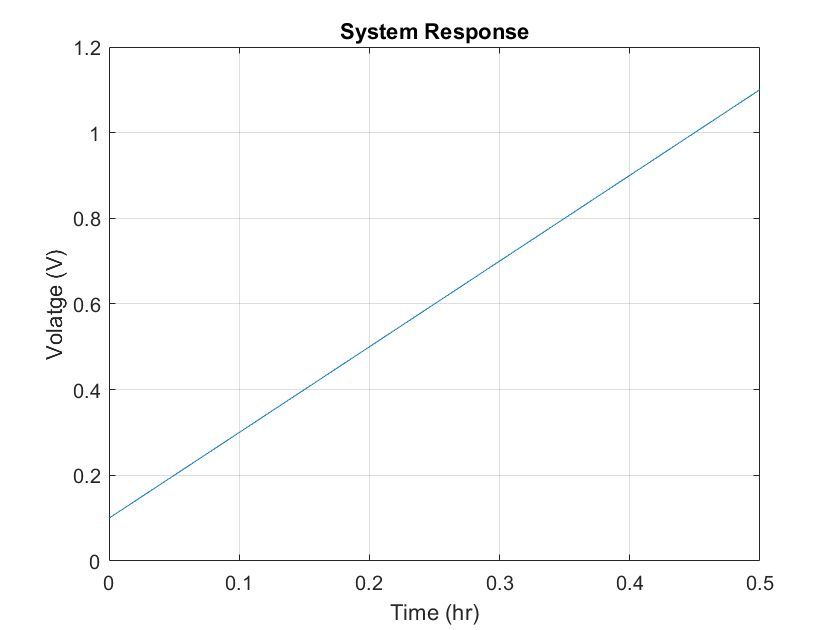


%Requirement 7

% Charge Capacity (Ah=3600 C)
Q=1;
% Gamma (dOCV/dSOC)
G=2;
% Equivalent Series Resistance (Ohms)
R=0.1;
% Equivalent Capacitance (Farads)
C=Q/G;
%Initial Voltage at 0 SOC (Volts)
V0=0;

A = [0];
B = [1/Q];
C = [G];
D = [R + V0];
sys = ss(A,B,C,D);
t = linspace(0, 0.5, 1000);                     
u = 1 + 0.2*sin(0.01*t);                                    
y = lsim(sys, u, t);                               
figure(21)
plot(t, y)
title("System Response")
xlabel('Time (hr)')
ylabel("Volatge (V)")
grid on

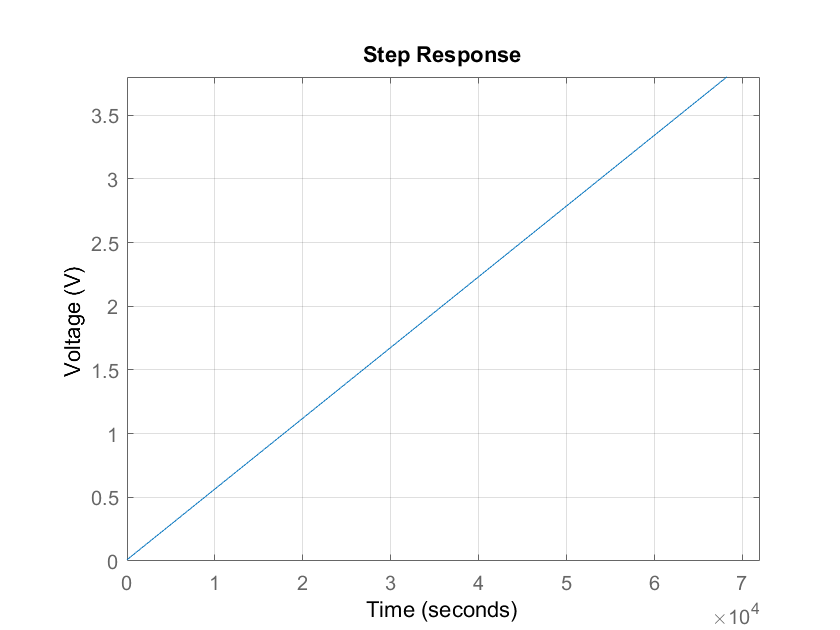

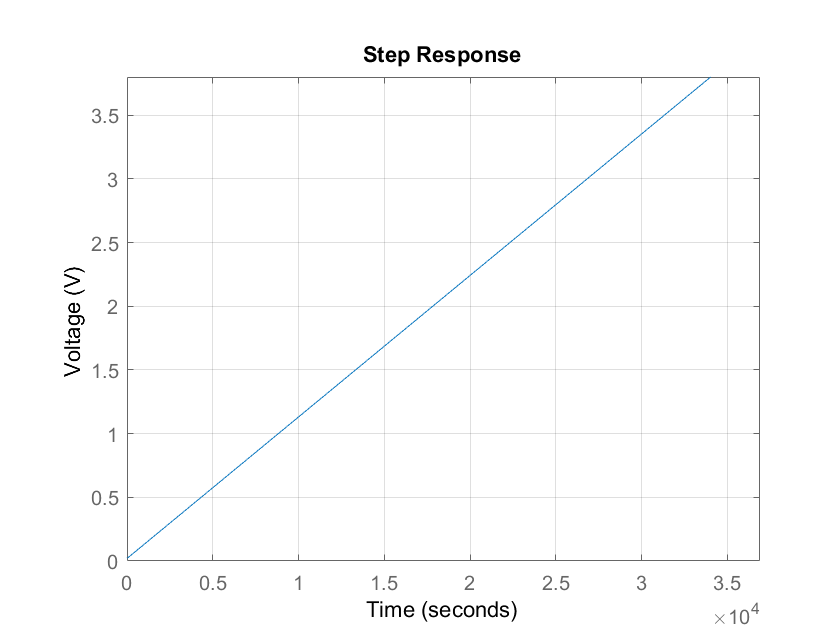

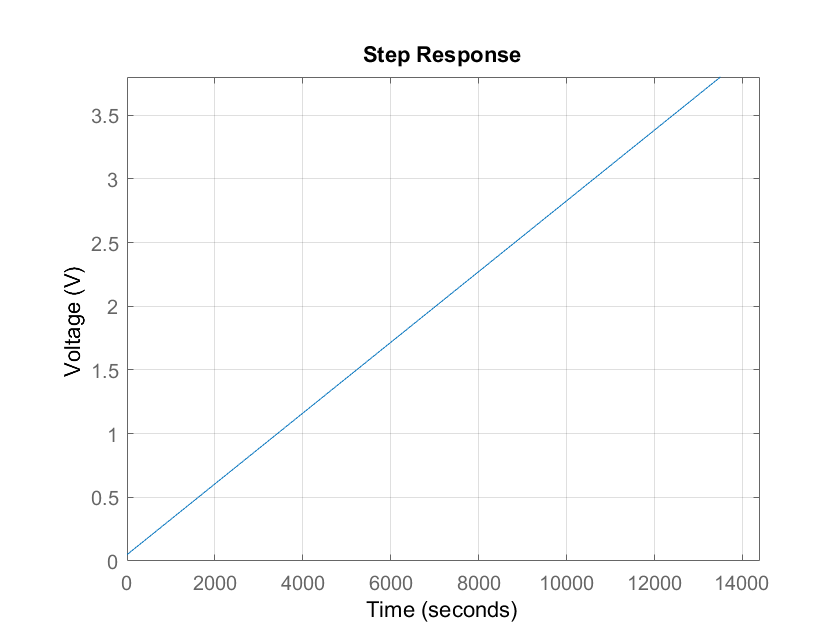

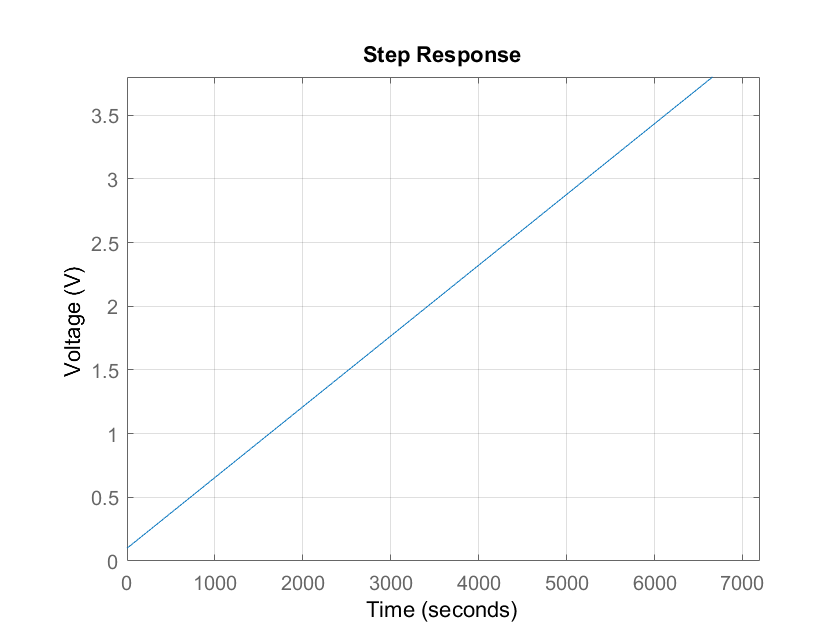

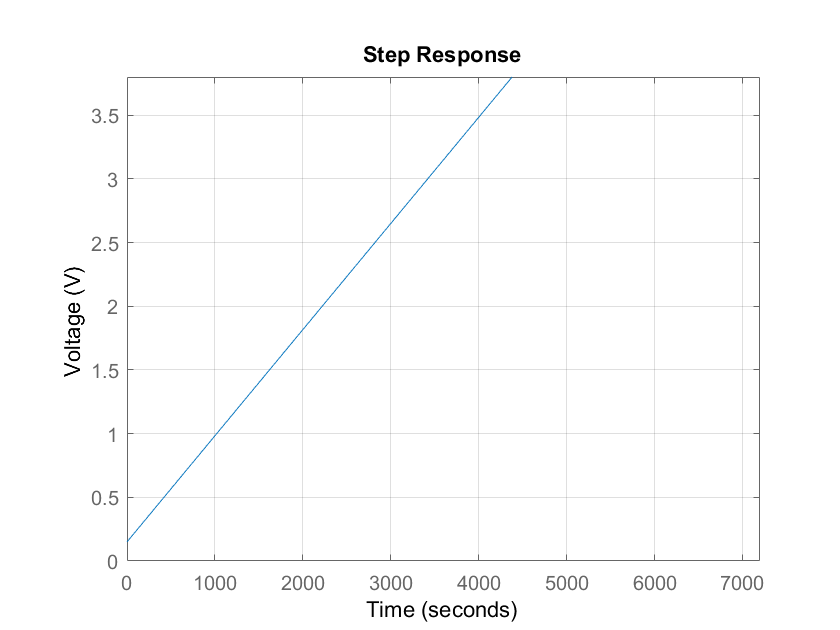

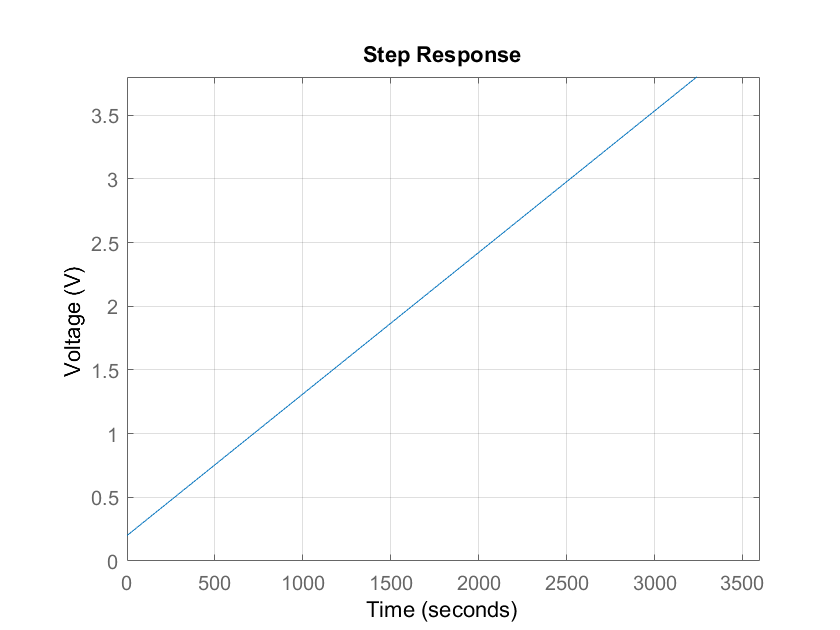


%Requirement 8

% Charge Capacity (Ah=3600 C)
Q=3600;
% Gamma (dOCV/dSOC)
G=2;
% Equivalent Series Resistance (Ohms)
R=0.1;
% RC Pair 1 Resistance (Ohms)
R1=0.01;
% RC Pair 2 Resistance (Ohms)
R2=0.01;
% RC Pair 1 Capacitance (Farads)
C1=600;
% RC Pair 2 Capacitance (Farads)
C2=10;
% Equivalent Capacitance (Farads)
C=Q/G;
%Initial Voltage at 0 SOC (Volts)
V0=0;

A = [0 0 0; 0 -1/(R1*C1) 0; 0 0 -1/(R2*C2)];
B = [1/Q; 0; 0];
C = [G 0 0; 0 1/C1 0; 0 0 1/C2];
D = [(R+V0); 0; 0];
sys = ss(A,B,C,D);
for i = 1:length(C_rate) 
    figure(21+i)
    opt = stepDataOptions('InputOffset',0 ,'StepAmplitude',C_rate(i));
    step(sys(1), t_f(i) ,opt) 
    ylabel("Voltage (V)")
    ylim([0 3.8])
    grid on
end               